%%APPENDIX A
%Plot the observed data in dBm vs. log10(r / r0), 
% where r is the distance between Tx and Rx. 
%On the samegraph plot the free-space model, 
% choosing P0 to give a reasonable fit to the x ≤ 0 data
% (where diffraction is not yet a big effect). 
% You can “eyeball” the fit, i.e., you don’t need to
%do a numerical minimization. 
%Part one
data_dBm = [-39 -37 -36 -41 -45 -43 -52 -42 -52 -62 -64 ...
    -60 -72 -64 -72 -68 -62 -79];
yr = 1.745; %in m
yt = 15.2; %in m
xt = 4.215; %in m
r0 = 16.959; %yt + yr%in m
rAdjacent = [0 2 4 6 8 10 12 14 16 18 20 22 24 26 28 ...
    30 32 34]; %in ft
conv = .3048;
r_m = zeros(1,18);
for j = 1:18
    r_m(j) = rAdjacent(j)*conv;
end
r = zeros(1,18);
for i = 1:18
    r(i) = sqrt(r_m(i)^2 + r0^2);
end
r; %For checking
roverr0 = log10(r/r0)

roverr0 =          0    0.0003    0.0011    0.0025    0.0044    0.0069    0.0099    0.0133    0.0173    0.0216    0.0264    0.0315    0.0371    0.0429    0.0490    0.0554    0.0621    0.0689


%Against wall , plot this point
r_LOS = sqrt(r0^2 + (4.215)^2)

r_LOS = 17.4750

r_LOS_dB = log10(r_LOS/r0)

r_LOS_dB = 0.0130

%Free Space Model
P0 = -43;
Pr_fs = P0 - 20*roverr0

Pr_fs =   -43.0000  -43.0056  -43.0224  -43.0502  -43.0889  -43.1381  -43.1975  -43.2666  -43.3451  -43.4323  -43.5277  -43.6309  -43.7411  -43.8578  -43.9804  -44.1083  -44.2410  -44.3780


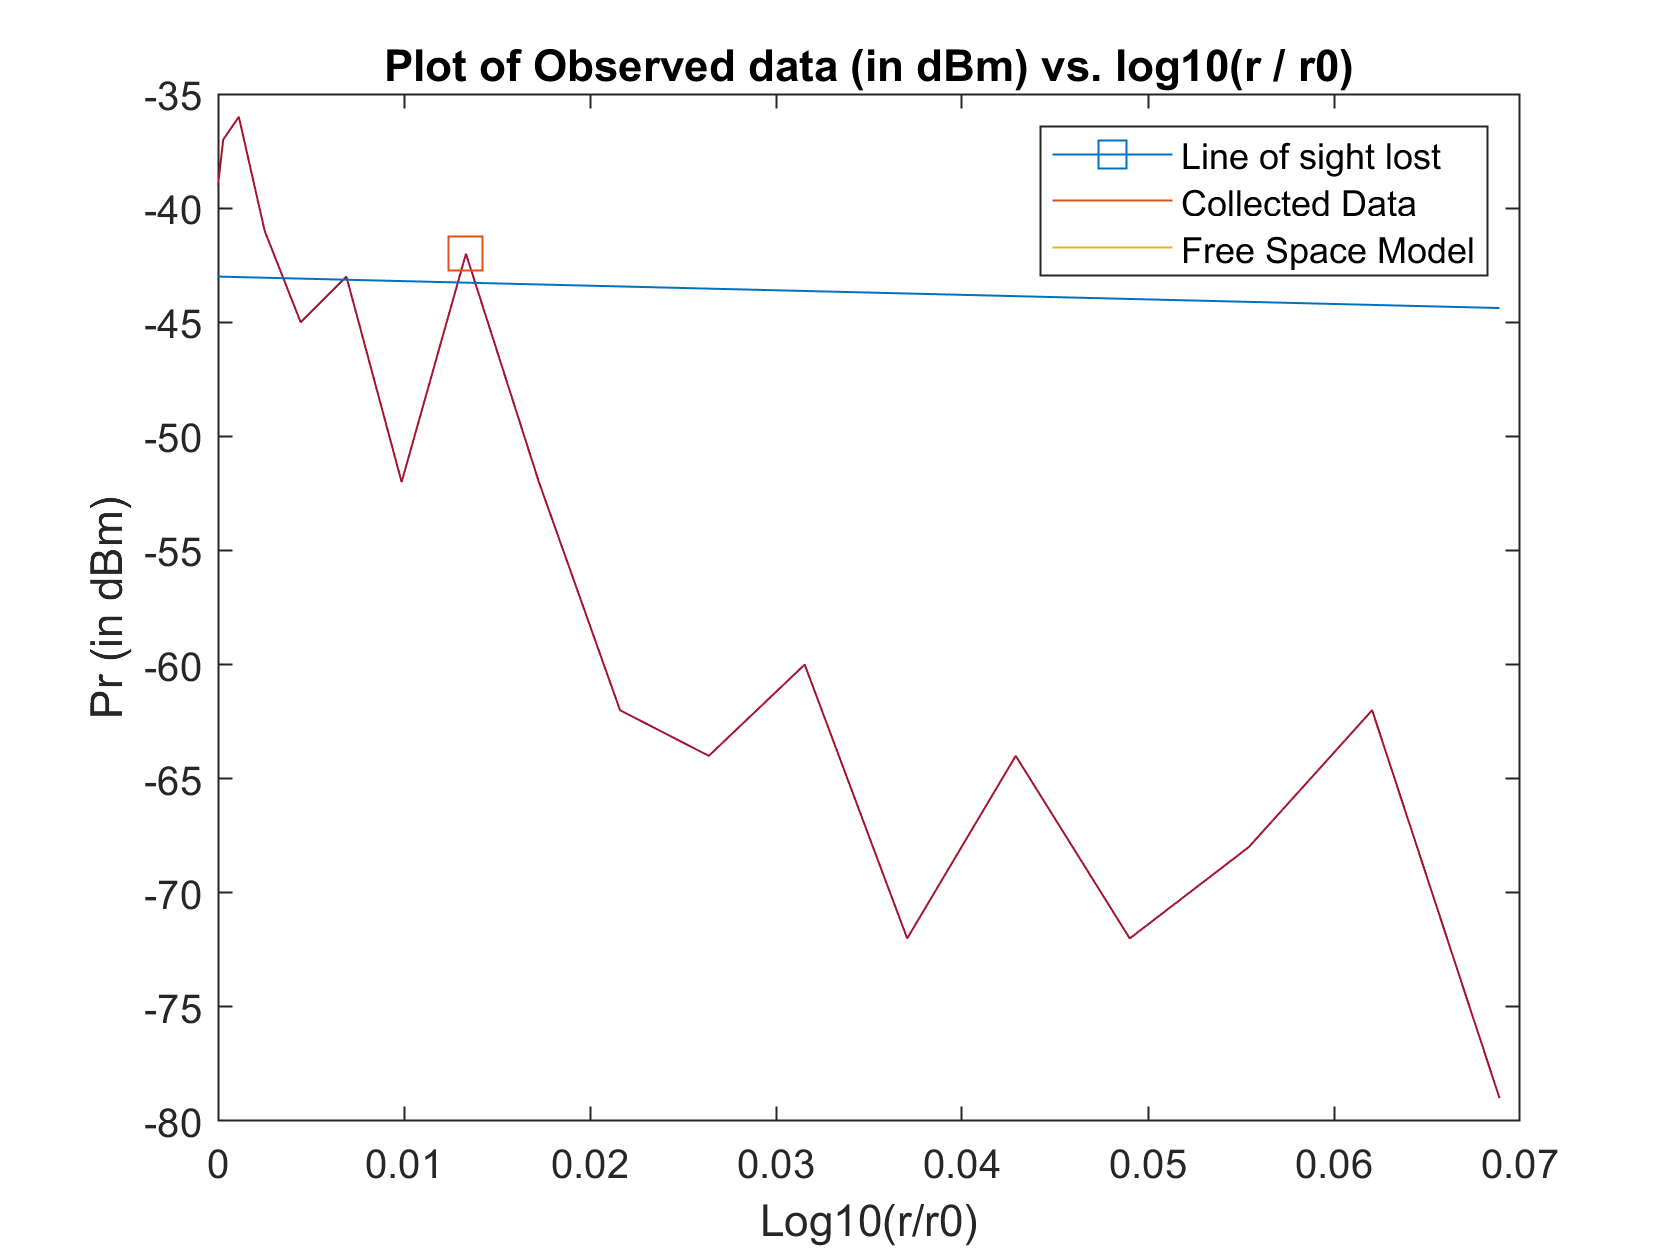

%Plot over range
hold on
plot(roverr0, data_dBm, roverr0, Pr_fs)
%This is to plot the point on the graph
%I realized when calculating by r_LOS_dB
%That this value is similar to our 8th data point 
%This code I found on a MATLAB forum, all credit
%to them
PointsPerPixels = 72/get(0,'ScreenPixelsPerInch');
plot(roverr0(8), data_dBm(8),'Marker','s','MarkerSize', 15 * PointsPerPixels)
xlabel('Log10(r/r0)')
ylabel('Pr (in dBm)')
title('Received power (in dBm) vs. log10(r / r0)')
legend('Line of sight lost','Collected Data', 'Free Space Model')
hold off

% I know my part 1 is right 
